## Price series with independent normally distributed log-returns

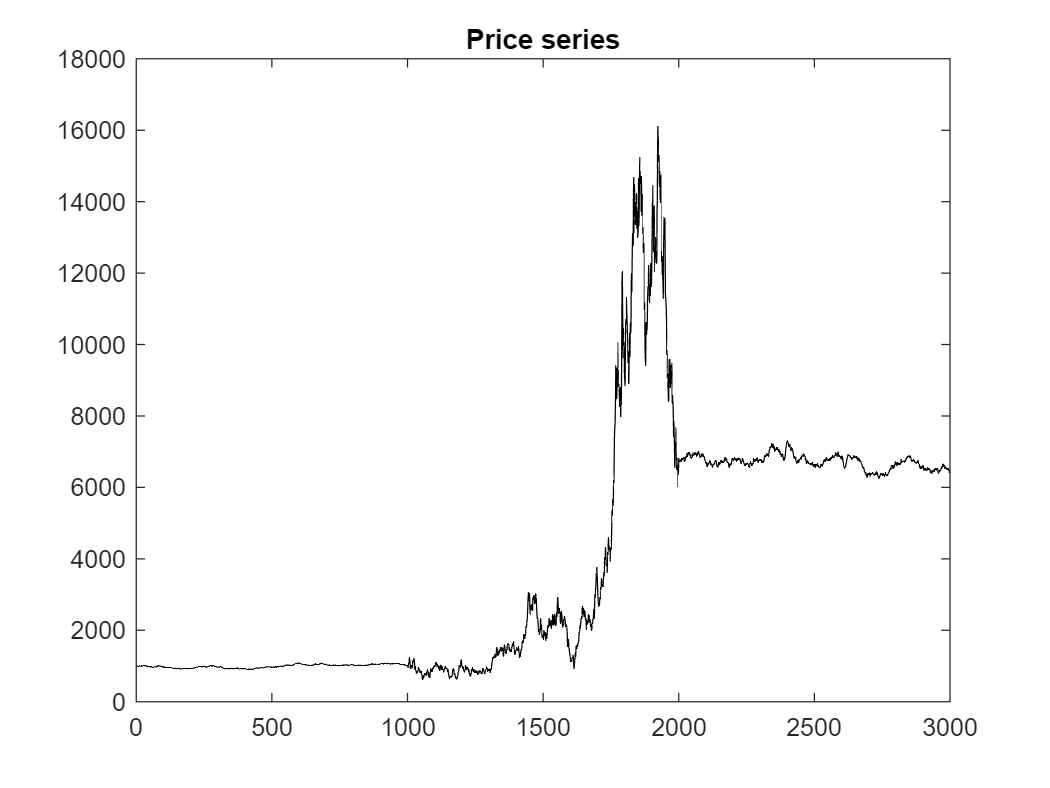

series_length = 1000;
price_series1 = zeros(1, series_length);
log_returns1 = normrnd(0, 0.005, series_length);
price_series1(1) = 1000; %initial price
for j = 2 : series_length
   price_series1(j) = exp(log_returns1(j-1)) * price_series1(j-1);
end 

price_series2 = zeros(1, series_length);
log_returns2 = normrnd(0, 0.05, series_length);
price_series2(1) = exp(log_returns1(end)) * price_series1(end); 
for j = 2 : series_length
   price_series2(j) = exp(log_returns2(j-1)) * price_series2(j-1);
end 

price_series3 = zeros(1, series_length);
log_returns3 = normrnd(0, 0.005, series_length);
price_series3(1) = exp(log_returns2(end)) * price_series2(end); %initial price
for j = 2 : series_length
   price_series3(j) = exp(log_returns3(j-1)) * price_series3(j-1);
end 

price_series = [price_series1, price_series2, price_series3];
 [C,L] = wavedec(price_series, 4, "haar"); 
    for i = 1:4 
        A(i,:) = wrcoef("a", C, L, "haar", i); 
        D(i,:) = wrcoef("d", C, L, "haar", i); 
    end
    
figure;
plot(price_series, "color", "black")
title("Price series")

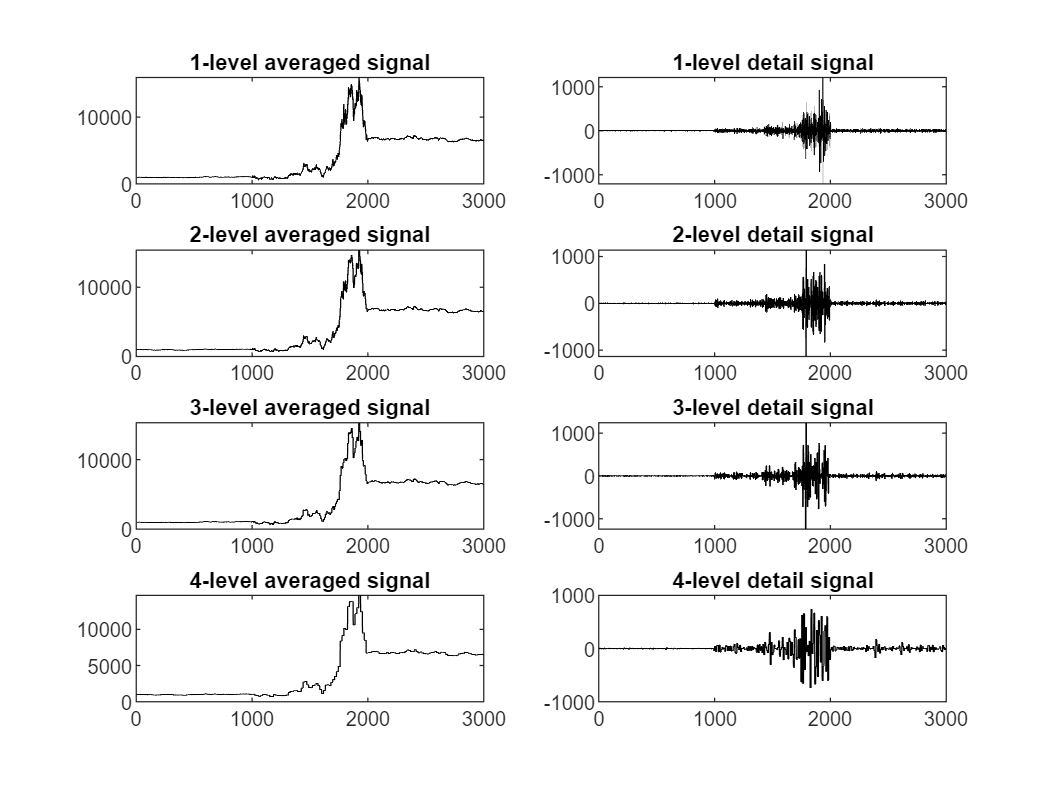


figure;
subplot(4, 2, 1)
plot(A(1, :), "color", "black")
title("1-level averaged signal")
subplot(4, 2, 2)
plot(D(1, :), "color", "black")
title("1-level detail signal")
subplot(4, 2, 3)
plot(A(2, :), "color", "black")
title("2-level averaged signal")
subplot(4, 2, 4)
plot(D(2, :), "color", "black")
title("2-level detail signal")
subplot(4, 2, 5)
plot(A(3, :), "color", "black")
title("3-level averaged signal")
subplot(4, 2, 6)
plot(D(3, :), "color", "black")
title("3-level detail signal")
subplot(4, 2, 7)
plot(A(4, :), "color", "black")
title("4-level averaged signal")
subplot(4, 2, 8)
plot(D(4, :), "color", "black")
title("4-level detail signal")

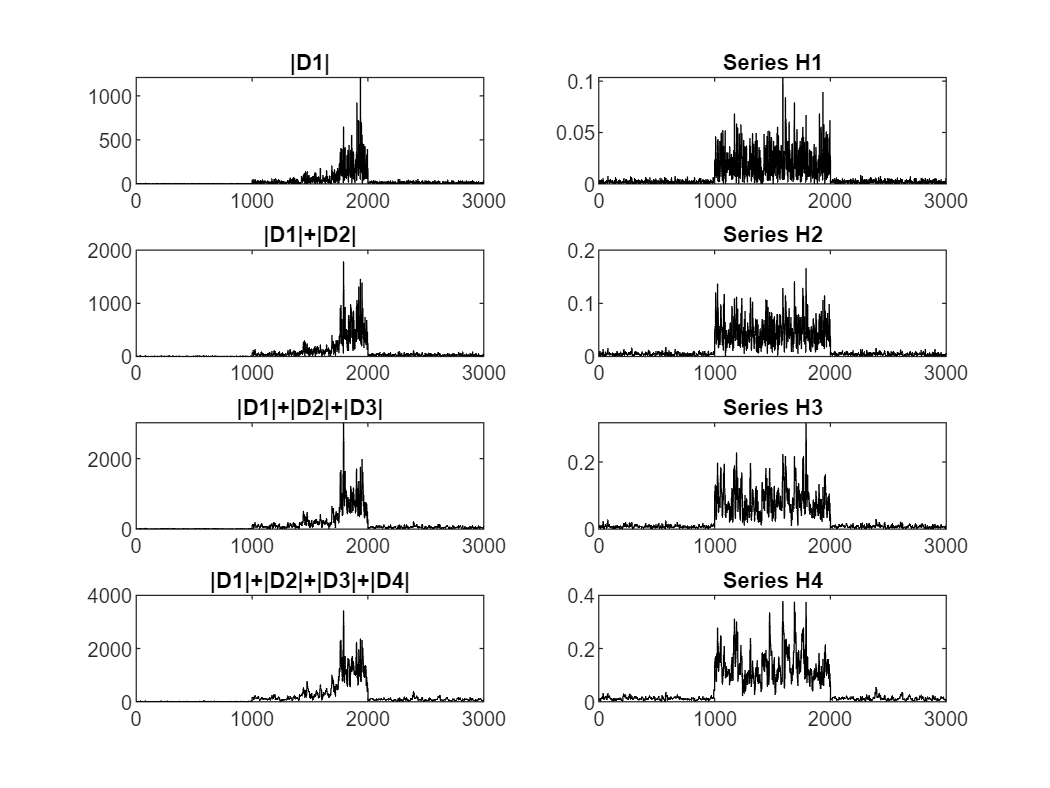


D1 = abs(D(1,:));
D2 = abs(D(1,:)) + abs(D(2,:));
D3 = abs(D(1,:)) + abs(D(2,:)) + abs(D(3,:));
D4 = abs(D(1,:)) + abs(D(2,:)) + abs(D(3,:)) + abs(D(4,:));

H1 =  abs(D(1,:)) ./ abs(A(1,:));
H2 = (abs(D(1,:)) + abs(D(2,:))) ./ abs(A(2,:));
H3 = (abs(D(1,:)) + abs(D(2,:)) + abs(D(3,:))) ./ abs(A(3,:));
H4 = (abs(D(1,:)) + abs(D(2,:)) + abs(D(3,:)) + abs(D(4,:))) ./ abs(A(4,:));

figure;
subplot(4, 2, 1)
plot(D1 , "color", "black")
title("|D1|")
subplot(4, 2, 3)
plot(D2, "color", "black")
title("|D1|+|D2|")
subplot(4, 2, 5)
plot(D3, "color", "black")
title("|D1|+|D2|+|D3|")
subplot(4, 2, 7)
plot(D4, "color", "black")
title("|D1|+|D2|+|D3|+|D4|")

subplot(4, 2, 2)
plot(H1, "color", "black")
title("Series H1")
subplot(4, 2, 4)
plot(H2, "color", "black")
title("Series H2")
subplot(4, 2, 6)
plot(H3, "color", "black")
title("Series H3")
subplot(4, 2, 8)
plot(H4, "color", "black")
title("Series H4")

## Price series with independent scaled Student’s t-distributed log-returns

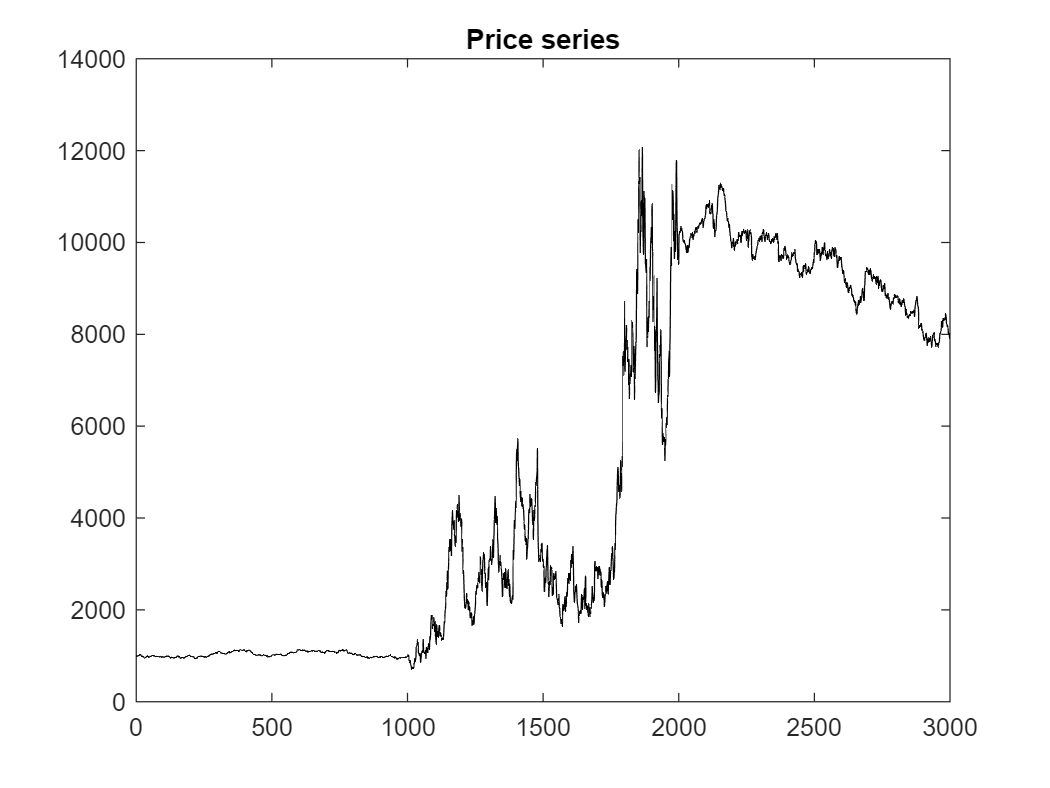

series_length = 1000;
price_series1 = zeros(1, series_length);
log_returns1 = 0.005 * trnd(4, series_length);
price_series1(1) = 1000; %initial price
for j = 2 : series_length
   price_series1(j) = exp(log_returns1(j-1)) * price_series1(j-1);
end 

price_series2 = zeros(1, series_length);
log_returns2 = 0.05 * trnd(4, series_length);
price_series2(1) = exp(log_returns1(end)) * price_series1(end);
for j = 2 : series_length
   price_series2(j) = exp(log_returns2(j-1)) * price_series2(j-1);
end 

price_series3 = zeros(1, series_length);
log_returns3 = 0.005 * trnd(4, series_length);
price_series3(1) = exp(log_returns2(end)) * price_series2(end); %initial price
for j = 2 : series_length
   price_series3(j) = exp(log_returns3(j-1)) * price_series3(j-1);
end 

price_series = [price_series1, price_series2, price_series3];
 [C,L] = wavedec(price_series, 4, "haar"); 
    for i = 1:4 
        A(i,:) = wrcoef("a", C, L, "haar", i); 
        D(i,:) = wrcoef("d", C, L, "haar", i); 
    end

figure;
plot(price_series, "color", "black")
title("Price series")

## Definition of the series H_i, i=1, ..., 4

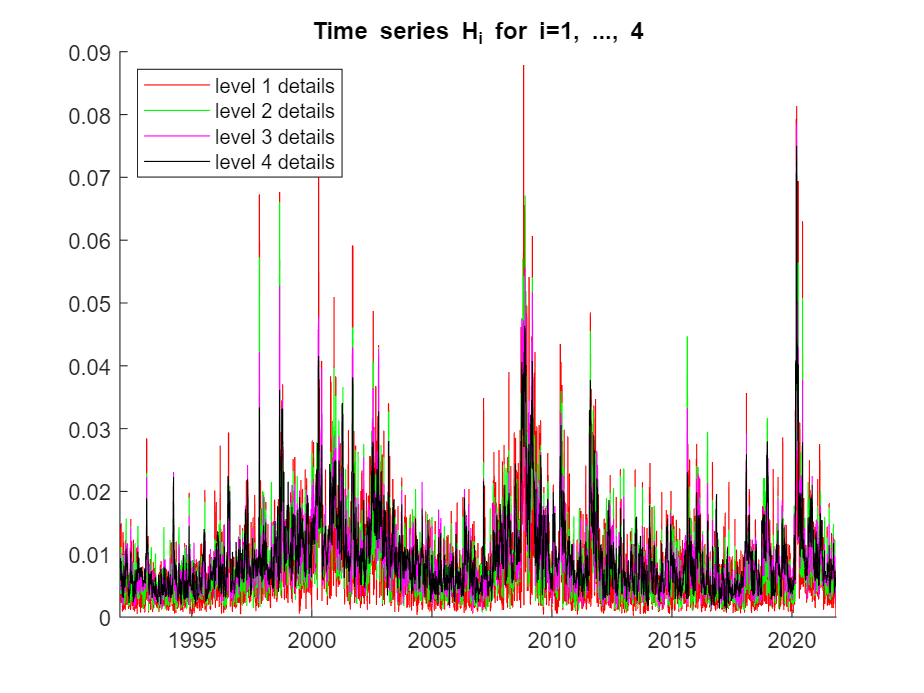

w = "haar";
n = 4;
[H1_dija, H2_dija, H3_dija, H4_dija] = definition_hi_signal(AdjClose_DIJA, w, n);
[H1_gspc, H2_gspc, H3_gspc, H4_gspc] = definition_hi_signal(AdjClose_GSPC, w, n);
[H1_nasdaq, H2_nasdaq, H3_nasdaq, H4_nasdaq] = definition_hi_signal(AdjClose_NASDAQ, w, n);
[H1_rut, H2_rut, H3_rut, H4_rut] = definition_hi_signal(AdjClose_RUT, w, n);
H1 = abs(H1_rut) + abs(H1_gspc) + abs(H1_nasdaq) + abs(H1_dija);
H2 = abs(H2_rut) + abs(H2_gspc) + abs(H2_nasdaq) + abs(H2_dija);
H3 = abs(H3_rut) + abs(H3_gspc) + abs(H3_nasdaq) + abs(H3_dija);
H4 = abs(H4_rut) + abs(H4_gspc) + abs(H4_nasdaq) + abs(H4_dija);

H1=H1./norm(H1);
H2=H2./norm(H2);
H3=H3./norm(H3);
H4=H4./norm(H4);

figure;
hold on
plot(Date, H1, 'color','r')
plot(Date, H2, 'color', 'g')
plot(Date, H3, 'color', 'magenta')
plot(Date, H4,'color','black')
legend('level 1 details', 'level 2 details', 'level 3 details', 'level 4 details', Location="northwest")
title("Time series H_i for i=1, ..., 4")
hold off;

## Moving average

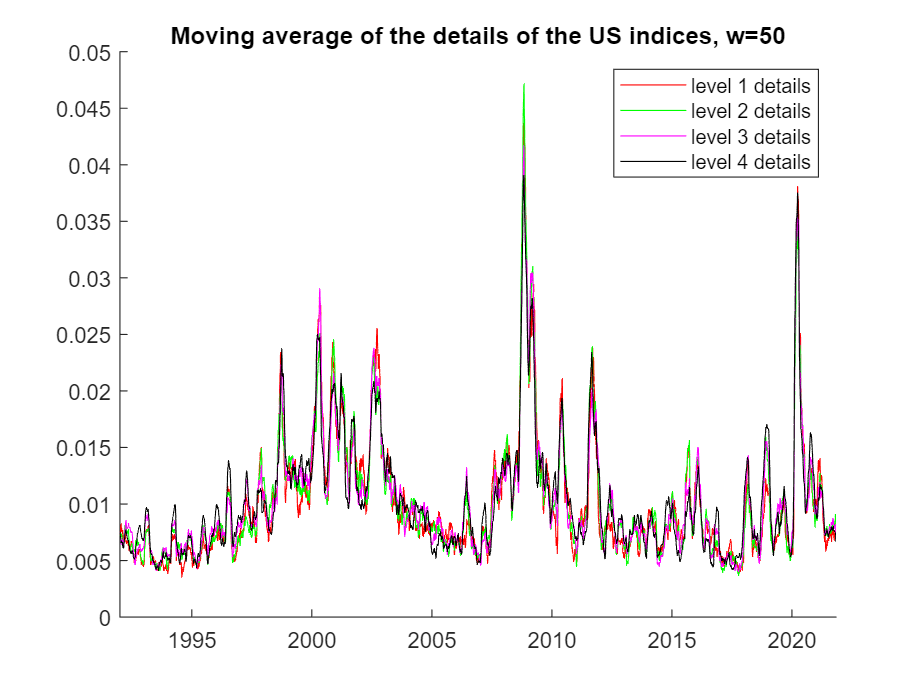

window = 50;
mean1 = movmean(H1, window);
mean1 = mean1 ./ norm(mean1);
mean2 = movmean(H2,window); 
mean2 = mean2 ./ norm(mean2);
mean3 = movmean(H3,window); 
mean3 = mean3 ./ norm(mean3);
mean4 = movmean(H4,window);
mean4 = mean4 ./ norm(mean4);
figure;
hold on
plot(Date, mean1, 'color','r')
plot(Date, mean2, 'color', 'green')
plot(Date, mean3, 'color', 'magenta')
plot(Date, mean4, 'color','black')
legend('level 1 details', 'level 2 details', 'level 3 details', 'level 4 details')
title("Moving average of the details of the US indices, w=50")
hold off

## Moving energy

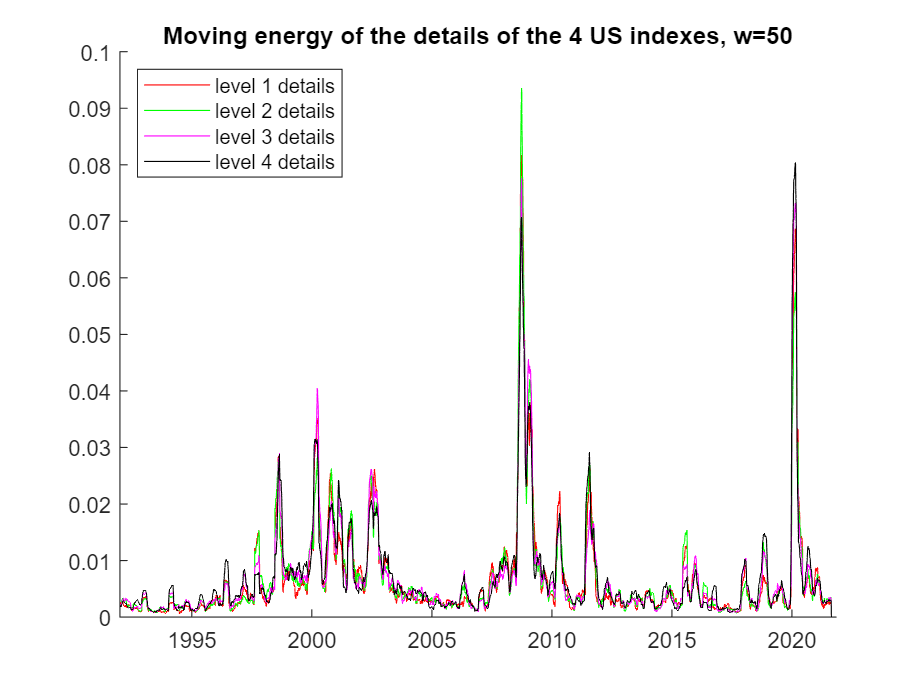

window = 50;
moven1 = moving_energy(H1,window);
moven1 = moven1 ./ norm(moven1);
moven2 = moving_energy(H2,window);
moven2 = moven2 ./ norm(moven2);
moven3 = moving_energy(H3,window);
moven3 = moven3 ./ norm(moven3);
moven4 = moving_energy(H4,window);
moven4 = moven4 ./ norm(moven4);
figure;
hold on
plot(Date, moven1, 'color', 'r')
plot(Date, moven2, 'color', 'g')
plot(Date, moven3, 'color', 'magenta')
plot(Date, moven4, 'color', 'black')
legend('level 1 details', 'level 2 details', 'level 3 details', 'level 4 details', Location = "northwest")
title("Moving energy of the details of the 4 US indexes, w=50")
hold off

## Noise reduction

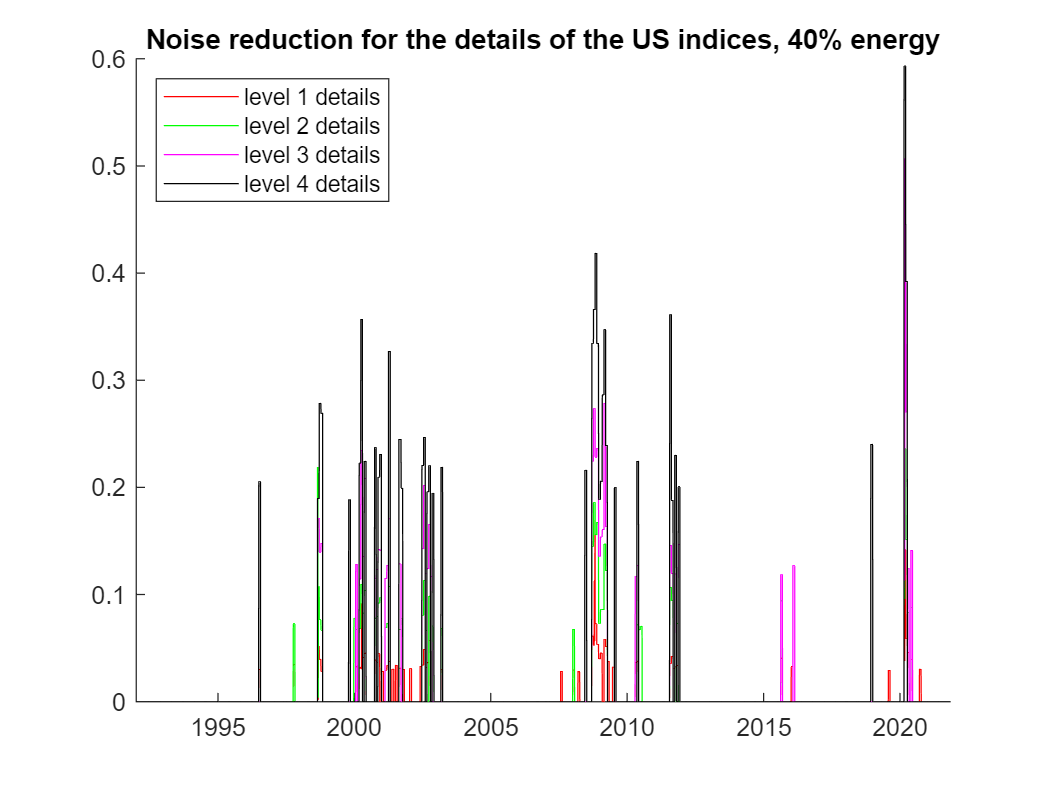

w = 'haar';
en_ret = 0.4;
thr_met = "h"; 
n = 4;
s_rec_H1 = noise_reduction(w, en_ret, thr_met, H1, n);
s_rec_H2 = noise_reduction(w, en_ret, thr_met, H2, n);
s_rec_H3 = noise_reduction(w, en_ret, thr_met, H3, n);
s_rec_H4 = noise_reduction(w, en_ret, thr_met, H4, n);
figure;
hold on;
plot(Date, s_rec_H1, 'color', 'r')
plot(Date, s_rec_H2, 'color', 'g')
plot(Date, s_rec_H3, 'color', 'magenta')
plot(Date, s_rec_H4, 'color', 'black')
legend('level 1 details', 'level 2 details', 'level 3 details', 'level 4 details', Location = "northwest")
title("Noise reduction for the details of the US indices, 40% energy")
hold off;

## Critical dates

w = "haar";
en_ret = 0.4;
thr_met = "h"; 
n = 4;
critical_dates = get_critical_dates(w, en_ret, thr_met, Date, H1, H2, H3, H4, n);


## Early warning signals using H_i, i=1, ..., 4

w = "haar"; 
n = 4; 
en_ret = 0.4;
thr_met = "h"; 
counter = zeros(length(critical_dates), 1);
for date_index = 1 : length(critical_dates)
    index = find(Date == critical_dates(date_index));
    subset= [index - 15 : index + 15];
    for i = 1 : length(subset)
        [AdjClose_RUT_mirr, AdjClose_GSPC_mirr, AdjClose_DIJA_mirr, AdjClose_NASDAQ_mirr]=recreate_dataset(i,subset, AdjClose_RUT, AdjClose_GSPC, AdjClose_DIJA, AdjClose_NASDAQ);
        [H1_dija, H2_dija, H3_dija, H4_dija] = definition_hi_signal(AdjClose_DIJA_mirr, w, n);
        [H1_gspc, H2_gspc, H3_gspc, H4_gspc] = definition_hi_signal(AdjClose_GSPC_mirr, w, n);
        [H1_nasdaq, H2_nasdaq, H3_nasdaq, H4_nasdaq] = definition_hi_signal(AdjClose_NASDAQ_mirr, w, n);
        [H1_rut, H2_rut, H3_rut, H4_rut] = definition_hi_signal(AdjClose_RUT_mirr, w, n);
        H1 = abs(H1_rut) + abs(H1_gspc) + abs(H1_nasdaq) + abs(H1_dija);
        H2 = abs(H2_rut) + abs(H2_gspc) + abs(H2_nasdaq) + abs(H2_dija);
        H3 = abs(H3_rut) + abs(H3_gspc) + abs(H3_nasdaq) + abs(H3_dija);
        H4 = abs(H4_rut) + abs(H4_gspc) + abs(H4_nasdaq) + abs(H4_dija);
        critical_dates_rec=get_critical_dates(w, en_ret, thr_met, Date, H1, H2, H3, H4, n);
        if any(critical_dates_rec == critical_dates(date_index))
            counter(date_index) = counter(date_index) + 1;
        end
    end
end

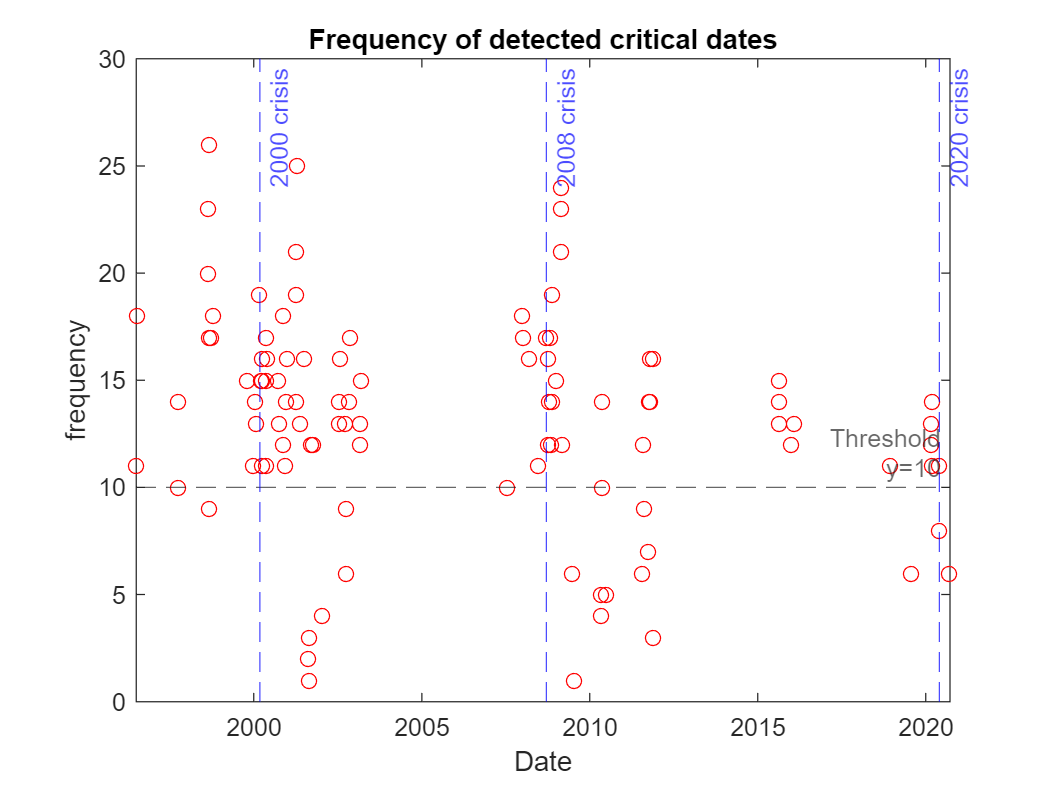

plot(critical_dates, counter, 'o', 'color', 'r')
title("Frequency of detected critical dates")
xlabel('Date')
ylabel('frequency')
hold on
yline(10, '--', {'Threshold', 'y=10'})
xline([critical_dates(16) critical_dates(62) critical_dates(103)], '--b', {'2000 crisis', '2008 crisis', '2020 crisis'})
hold off

threshold = 10;
%2000 crisis
indexes_2000 = intersect(find(counter >= threshold), find(critical_dates < critical_dates(16)));
critical_dates(indexes_2000) 

ans = 14×1 datetime array
   1996-07-02
   1996-07-12
   1997-10-07
   1997-10-08
   1998-08-27
   1998-08-28
   1998-09-01
   1998-09-09
   1998-09-30
   1998-10-16
   1999-10-28
   1999-12-29
   2000-01-20
   2000-01-25


%2008 crisis
indexes_thr1 = find(counter >= threshold);
indexes_thr2 = intersect(find(critical_dates >= critical_dates(57)), find(critical_dates < critical_dates(62)));
indexes_2008 = intersect(indexes_thr2, indexes_thr1);
critical_dates(indexes_2008)

ans = 5×1 datetime array
   2007-07-26
   2008-01-04
   2008-01-07
   2008-03-14
   2008-06-25


%2020 crisis
indexes_thr1 = find(counter >= threshold);
indexes_thr2 = intersect(find(critical_dates > critical_dates(98)), find(critical_dates < critical_dates(103)));
indexes_2020 = intersect(indexes_thr2, indexes_thr1);
critical_dates(indexes_2020)

ans = 4×1 datetime array
   2020-03-06
   2020-03-09
   2020-03-10
   2020-03-12


## Definition of the series W_i, i=1, ..., 4

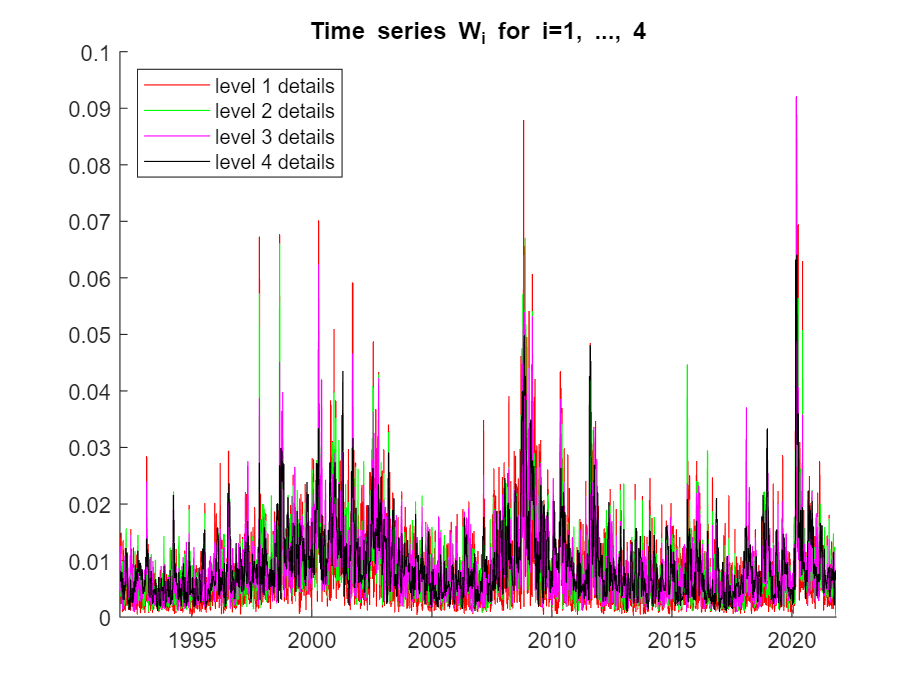

[W1, W2, W3, W4] = series_wi_definition(AdjClose_DIJA, AdjClose_GSPC, AdjClose_NASDAQ, AdjClose_RUT);
W1 = W1 ./ norm(W1);
W2 = W2 ./ norm(W2);
W3 = W3 ./ norm(W3);
W4 = W4 ./ norm(W4);
figure;
hold on
plot(Date, W1, 'color','r')
plot(Date, W2, 'color', 'g')
plot(Date, W3, 'color', 'magenta')
plot(Date, W4,'color','black')
legend('level 1 details', 'level 2 details', 'level 3 details', 'level 4 details', Location="northwest")
title("Time series W_i for i=1, ..., 4")
hold off

## Early warning signals using W_i, i=1, ..., 4 

Part which differs from the piece of code to get early warning signals for the part using Haar wavelets.

for date_index = 1 : length(critical_dates)
    index = find(Date == critical_dates(date_index));
    subset = [index - 15 : index + 15];
    for i = 1 : length(subset)
        [AdjClose_RUT_mirr, AdjClose_GSPC_mirr, AdjClose_DIJA_mirr, AdjClose_NASDAQ_mirr] = recreate_dataset(i, subset, AdjClose_RUT, AdjClose_GSPC, AdjClose_DIJA, AdjClose_NASDAQ);
        [W1, W2, W3, W4] = series_wi_definition(AdjClose_DIJA_mirr, AdjClose_GSPC_mirr, AdjClose_NASDAQ_mirr, AdjClose_RUT_mirr);
        critical_dates_rec = get_critical_dates(w, en_ret, thr_met, Date, W1, W2, W3, W4, n);
        if any(critical_dates_rec == critical_dates(date_index))
            counter(date_index) = counter(date_index) + 1;
        end
    end
end

## FUNCTIONS USED

function [H1_s, H2_s , H3_s , H4_s]=definition_hi_signal(s,w,n)
    [C,L] = wavedec(s,n,w); %trend and fluctuation subsignals
    for i = 1:n %
        A(i,:) = wrcoef("a",C,L,w,i); %averaged signal
        D(i,:) = wrcoef("d",C,L,w,i); %detail signal
    end
    H1_s =  abs(D(1,:))./abs(A(1,:));
    H2_s = (abs(D(1,:))+abs(D(2,:)))./abs(A(2,:));
    H3_s = (abs(D(1,:))+abs(D(2,:))+abs(D(3,:)))./abs(A(3,:));
    H4_s = (abs(D(1,:))+abs(D(2,:))+abs(D(3,:))+abs(D(4,:)))./abs(A(4,:));
end


function [s] = moving_energy(x, w)
    s = zeros(1, length(x));
    for i = 1 : (length(x) - w)
        s(i) = norm(x(i : i + w))^2; 
    end
end


function [y] = cumenergy(x) 
    y = cumsum(x.^2) / (norm(x)^2);
end


function [s_reconstructed] = noise_reduction(wavelet, en_ret, thr_method, signal, n)
    [C, L] = wavedec(signal, n, wavelet); 
    dec = abs(sort( - abs(C))); 
    left = find(cumenergy(dec) >= en_ret); 
    thr = dec(left(1)); 
    Cthr = wthresh(C, thr_method, thr); 
    s_reconstructed = abs(waverec(Cthr, L, wavelet)); 
end


function [critical_dates] = get_critical_dates(w, en_ret, thr_met, Date, series1, series2, series3, series4, n)
    s_rec_1 = noise_reduction(w, en_ret, thr_met, series1, n);
    s_rec_2 = noise_reduction(w, en_ret, thr_met, series2, n);
    s_rec_3 = noise_reduction(w, en_ret, thr_met, series3, n);
    s_rec_4 = noise_reduction(w, en_ret, thr_met, series4, n);
    list = {};
    [~, l1] = findpeaks(s_rec_1);
    [~, l2] = findpeaks(s_rec_2);
    l2 = [l1 + 2^0, l2 + 2^1];
    [~, l3] = findpeaks(s_rec_3);
    l3 = [l2, l3 + 2^2];
    [~, l4] = findpeaks(s_rec_4);
    l4 = [l3, l4+2^3];
    list = [list, Date(l4)];
    critical_dates = unique(list, "rows"); 
end


function  [AdjClose_RUT_mirr, AdjClose_GSPC_mirr, AdjClose_DIJA_mirr, AdjClose_NASDAQ_mirr]=recreate_dataset(i, subset, AdjClose_RUT, AdjClose_GSPC, AdjClose_DIJA, AdjClose_NASDAQ)
    AdjClose_RUT_s = AdjClose_RUT(1 : subset(i));
    AdjClose_GSPC_s = AdjClose_GSPC(1 : subset(i));
    AdjClose_DIJA_s = AdjClose_DIJA(1 : subset(i));
    AdjClose_NASDAQ_s = AdjClose_NASDAQ(1 : subset(i));
    AdjClose_RUT_mirr = [AdjClose_RUT_s; flip(AdjClose_RUT_s(2 : end - 1))];
    AdjClose_GSPC_mirr = [AdjClose_GSPC_s; flip(AdjClose_GSPC_s(2 : end - 1))];
    AdjClose_DIJA_mirr = [AdjClose_DIJA_s; flip(AdjClose_DIJA_s(2 : end - 1))];
    AdjClose_NASDAQ_mirr = [AdjClose_NASDAQ_s; flip(AdjClose_NASDAQ_s(2 : end - 1))];
    % concatenate four times to be sure to obtain at least the same length as the original series
    AdjClose_RUT_mirr = [AdjClose_RUT_mirr; AdjClose_RUT_mirr; AdjClose_RUT_mirr; AdjClose_RUT_mirr];
    AdjClose_GSPC_mirr = [AdjClose_GSPC_mirr; AdjClose_GSPC_mirr; AdjClose_GSPC_mirr; AdjClose_GSPC_mirr];
    AdjClose_DIJA_mirr = [AdjClose_DIJA_mirr; AdjClose_DIJA_mirr; AdjClose_DIJA_mirr; AdjClose_DIJA_mirr];
    AdjClose_NASDAQ_mirr = [AdjClose_NASDAQ_mirr; AdjClose_NASDAQ_mirr; AdjClose_NASDAQ_mirr; AdjClose_NASDAQ_mirr];
    % troncate to get the same length as the original time series
    AdjClose_RUT_mirr = AdjClose_RUT_mirr(1:7515);
    AdjClose_GSPC_mirr = AdjClose_GSPC_mirr(1:7515);
    AdjClose_DIJA_mirr = AdjClose_DIJA_mirr(1:7515);
    AdjClose_NASDAQ_mirr = AdjClose_NASDAQ_mirr(1:7515);
end


function[series_1, series_2, series_3, series_4] = series_wi_definition(series_djia, series_gspc, series_nasdaq, series_rut)
    [dija_1, dija_2, dija_3, dija_4] = definition_wi_signal(series_djia);
    [gspc_1, gspc_2, gspc_3, gspc_4] = definition_wi_signal(series_gspc);
    [nasdaq_1, nasdaq_2, nasdaq_3, nasdaq_4] = definition_wi_signal(series_nasdaq);
    [rut_1, rut_2, rut_3, rut_4] = definition_wi_signal(series_rut);
    series_1 = dija_1 + gspc_1 + nasdaq_1 + rut_1;
    series_2 = dija_2 + gspc_2 + nasdaq_2 + rut_2;
    series_3 = dija_3 + gspc_3 + nasdaq_3 + rut_3;
    series_4 = dija_4 + gspc_4 + nasdaq_4 + rut_4;
end


function[s_level1, s_level2, s_level3, s_level4] = definition_wi_signal(signal)
    w = 'haar';
    s_level1 = w1_signal(signal, w);
    s_level2 = w2_signal(signal, w);
    s_level3 = w3_signal(signal, w);
    s_level4 = w4_signal(signal, w);
end


function [s_level1] = w1_signal(s, w)
    n = 1;
    [C,L] = wavedec(s, n, w);
    D = wrcoef("d", C, L, w, 1); 
    A = wrcoef("a", C, L, w, 1); 
    s_level1 =(abs(D))./A;
end


function [s_level2]=w2_signal(s,w)
    n = 2;
    [C, L] = wavedec(s, n, w);
    D = wrcoef("d", C, L, w, 1); 
    AA = wrcoef("a", C, L, w, 2); 
    AD = wrcoef("d", C, L, w, 2); 
    %decompose 1-level details
    [C, L] = wavedec(D, 1, w);
    DD = wrcoef("d", C, L, w, 1);
    s_level2 = (abs(AD) + abs(DD)) ./ AA;
end


function [s_level3] = w3_signal(s, w)
    n = 3;
    [C, L] = wavedec(s, n, w);
    D = wrcoef("d", C, L, w, 1); 
    AAA = wrcoef("a", C, L, w, 3);
    AD = wrcoef("d", C, L, w, 2); 
    AAD = wrcoef("d", C, L, w, 3);
    %decompose 1-level details
    [C, L] = wavedec(D, 2, w);
    DAD = wrcoef("d", C, L, w, 2);
    DD = wrcoef("d", C, L, w, 1);
    %decompose details of details
    [C, L] = wavedec(DD, 1, w);
    DDD = wrcoef("d", C, L, w, 1);
    %decompose details of averaged signal
    [C, L] = wavedec(AD, 1, w);
    ADD = wrcoef("d", C, L, w, 1);
    s_level3 = (abs(AAD) + abs(ADD) + abs(DAD) + abs(DDD)) ./ AAA;
end


function [s_level4] = w4_signal(s, w)
    n = 4;
    [C, L] = wavedec(s, n, w);
    D = wrcoef("d", C, L, w, 1); %D1
    AD = wrcoef("d", C, L, w, 2); %D2
    AAD = wrcoef("d", C, L, w, 3); %D3
    AAAD = wrcoef("d", C, L, w, 4); %D4
    AAAA = wrcoef("a", C, L, w, 4); %A4
    %decompose AAD at level  1
    [C, L] = wavedec(AAD, 1, w);
    AADD = wrcoef("d", C, L, w, 1);
    %decompose AD at level 2
    [C, L] = wavedec(AD, 2, w);
    ADAD = wrcoef("d", C, L, w, 2);
    ADD = wrcoef("d", C, L, w, 1);
    %decompose ADD at level 1
    [C, L] = wavedec(ADD, 1, w);
    ADDD = wrcoef("d", C, L, w, 1);
    %decompose D at level 3
    [C, L] = wavedec(D, 3, w);
    DAAD = wrcoef("d", C, L, w, 3);
    DAD = wrcoef("d", C, L, w, 2);
    DD = wrcoef("d", C, L, w, 1);
    %decompose DAD at level 1
    [C, L] = wavedec(DAD, 1, w);
    DADD = wrcoef("d", C, L, w, 1);
    %decompose DD at level 2
    [C,L] = wavedec(DD, 2, w);
    DDD = wrcoef("d", C, L, w, 2);
    DDAD = wrcoef("d", C, L, w, 2);
    %decompose DDD at level 1
    [C, L] = wavedec(DDD, 1, w);
    DDDD = wrcoef("d", C, L, w, 1);
    s_level4 = (abs(AAAD) + abs(AADD) + abs(ADAD) + abs(ADDD) + ...
        abs(DAAD) + abs(DADD) + abs(DDAD) + abs(DDDD)) ./ AAAA;
end